Gruppe: Batuhan Aykut (6697882), Lars Annuth (1140146), Liza Thöne (9434335)

**Aufgabe 1:**

Ermitteln Sie den Verlauf für den Schwimmwinkel und die Giergeschwindigkeit für den Fall, dass Sie den Radlenkwinkel auf delta = 5° bei einer Geschwindigkeit von v = 18 m/s * springen lassen,

Verwenden Sie dafür folgende Parameter: m = 2000kg, J = 4000kgm², lv = 1.43m, lh = 1.4m, cv = 70000 N/rad , ch = 140000 N/rad

Berechnen Sie die Lösung mit Hilfe von Matlab. Stellen Sie die Ergebnisse grafisch dar, geben Sie die Winkel bzw. Winkelgeschwindigkeit in ° bzw. °/s an.

Parameter und deren Einheiten

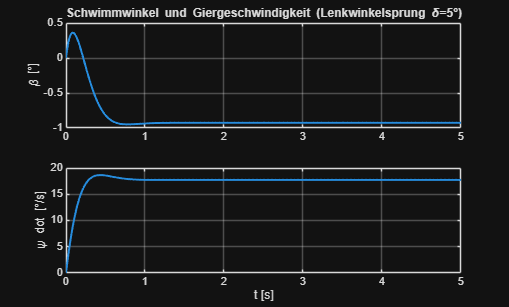

m  = 2000;      % Masse [kg]
J  = 4000;      % Massenträgheitsmoment Gierbewegung [kgm²]
lv = 1.43;      % Schwerpunktabstand zur Vorderachse [m]
lh = 1.4;       % Schwerpunktabstand zur Hinterachse [m]
cv = 70000;     % Schräglaufsteifigkeit Vorderachse [N/rad]
ch = 140000;    % Schräglaufsteifigkeit Hinterachse [N/rad]
v  = 18;        % Fahrzeuggeschwindigkeit [m/s]

d = deg2rad(5);   % Radlenkwinkel [rad]

%% Zustandsraummatrix

A = [-(cv+ch)/(m*v),  (ch*lh - cv*lv)/(m*v^2) - 1;
     (ch*lh - cv*lv)/J, -(cv*lv^2 + ch*lh^2)/(J*v)];

B = [cv/(m*v);
     cv*lv/J];

C = eye(2);
D = [0;0];

sys = ss(A,B,C,D);

%% Simulation
t = 0:0.01:5;               % Zeit [s]
u = d * ones(size(t));      % δ(t) = 5° konstant ab t=0

[y,t,x] = lsim(sys,u,t);

beta = y(:,1);       % β [rad]
psi_dot = y(:,2);    % Ψ̇  [rad/s]

%% Umrechnung in Grad
beta_deg = rad2deg(beta);         % [°]
psi_dot_deg = rad2deg(psi_dot);   % [°/s]

%% Plot
figure
subplot(2,1,1)
plot(t, beta_deg, 'LineWidth', 1.5)
grid on
ylabel('\beta [°]')
title('Schwimmwinkel und Giergeschwindigkeit (Lenkwinkelsprung \delta=5°)')

subplot(2,1,2)
plot(t, psi_dot_deg, 'LineWidth', 1.5)
grid on
ylabel('\psi dot [°/s]')
xlabel('t [s]')

Aufgabe 2:

Aufgabe 3: 